# Zadanie 5.1

**Dla reaktora PWR z Zad. 2.2 (użyj wyników). Oblicz dla kanału gorącego:**

**1. Wykreśl maksymalną moc liniowa oraz strumień ciepła. Określ moc kanału gorącego. Sprawdz warunek normalizacji mocy.**

**2. Oblicz krytyczny strumień ciepła wzdłuż kanału korzystając z korelacji Levitan & Lantsman. Wykonaj wykres CHF wzdłuż kanału. Sprawdź zakres stosowalności korelacji.**

**3. Oblicz współczynnik odjeścia od wrzenia pęcherzykowego w najbardziej obciążonym cieplnie miejscu. Wykonaj wykres DNBR wzdłuż kanału.**

**4. Określ wartość MDNBR oraz lokalizację.**

Uruchom zadanie 2.2, tak żeby jego wyniki były w pamięci.

%run('C:\OneDrive\OneDrive - Politechnika Warszawska\DROPBOX\STUDENT MATERIALS\SPECJALNOSC_EJ_2024\ZagadnieniaCieplnoPrzeplywowe-Cwiczenia\Cw2\my\zadanie2_2_rev3.mlx');
%run('C:\OneDrive\OneDrive - Politechnika Warszawska\DROPBOX\STUDENT MATERIALS\SPECJALNOSC_EJ_2024\ZagadnieniaCieplnoPrzeplywowe-Cwiczenia\Cw2\my\zadanie2_2_rev2.mlx');
%run('C:\OneDrive\OneDrive - Politechnika Warszawska\DROPBOX\STUDENT MATERIALS\SPECJALNOSC_EJ_2024\ZagadnieniaCieplnoPrzeplywowe-Cwiczenia\Cw2\my\zadanie2_2_rev2_2025.mlx');
%run('C:\OneDrive\OneDrive - Politechnika Warszawska\DROPBOX\STUDENT MATERIALS\2025_SPECJALNOSC_OMNIS_EJ\ZagadnieniaCieplnoPrzeplywowe\Cw2\my\zadanie2_2_rev2_2025.mlx');

clc; close all; % zamknij wykresy i wyczyść okno.

Geometria paliwa

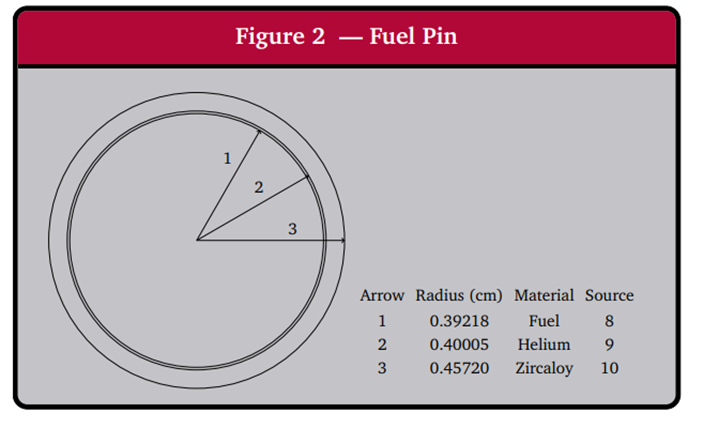

format long g
r_Co = 0.45720/100 % primień zew. koszulki

r_Co =                   0.004572


Z zadania 2.2 mamy wyniki dla moc liniową, strumienie ciepła oraz moc kanału.

format short g
% powtorzenie wyników 2.2
wyniki22max = [z' q_prim_max' q_bis_max' ]

wyniki22max =          -2.1       1382.8        46332
      -2.0576       2554.7        85597
      -2.0152       3724.1   1.2478e+05
      -1.9727       4889.9   1.6384e+05
      -1.9303       6051.1   2.0275e+05
      -1.8879       7206.4   2.4146e+05
      -1.8455       8354.9   2.7994e+05
       -1.803       9495.3   3.1815e+05
      -1.7606        10627   3.5606e+05
      -1.7182        11748   3.9362e+05
      -1.6758        12857    4.308e+05
      -1.6333        13955   4.6757e+05
      -1.5909        15039    5.039e+05
      -1.5485        16108   5.3973e+05
      -1.5061        17163   5.7505e+05


**1. Wykreśl maksymalną moc liniowa oraz strumień ciepła. Określ moc kanału gorącego. **

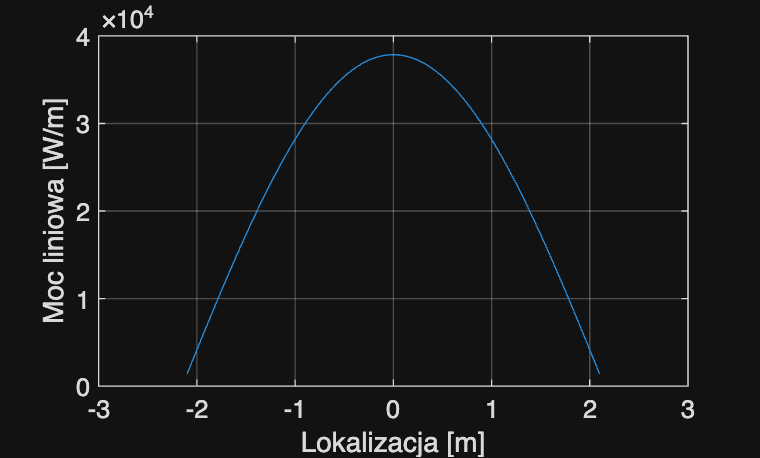

% Wykres mocy liniowej i strumienia
plot(z,q_prim_max); 
grid on; box on; xlabel('Lokalizacja [m]'); ylabel('Moc liniowa [W/m]');

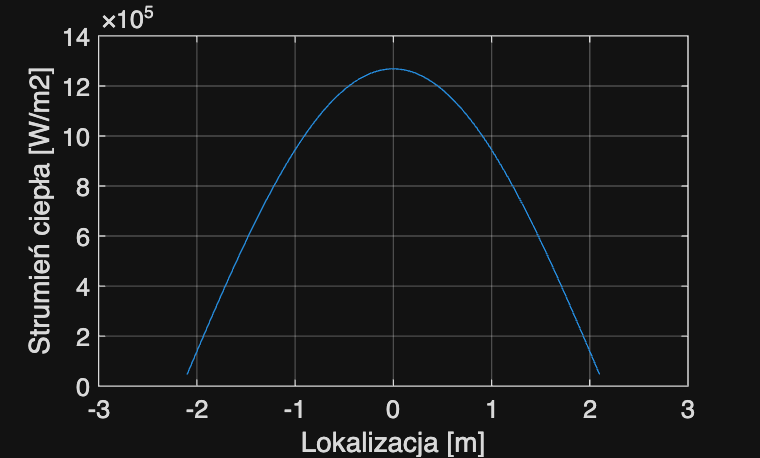

plot(z,q_bis_max); 
grid on; box on; xlabel('Lokalizacja [m]'); ylabel('Strumień ciepła [W/m2]');

% Maksymalna moc liniowa
q0_prim_max

q0_prim_max =         37861


% Maksymalny strumień ciepła
q0_bis_max = q0_prim_max/(2*pi*r_Co)

q0_bis_max =     1.318e+06


% Moc kanalu - średnia = Moc rdzenia / ilość kanałów
q_kanal 

q_kanal =         72027


% Moc kanału gorącego = wsp. nierównomierności * moc kanału średniego
Pxy

Pxy =         1.438


q_kanal_max =  Pxy *  q_kanal

q_kanal_max =    1.0357e+05


**2. Sprawdz warunek normalizacji mocy**

Moc kanału gorącego musi być równa całce po rozkładzie mocy liniowej wzdłuż kanału.


$$q_{max}= \int_{-H/2}^{H/2} q'(z)dz $$


gdzie: q to moc kanału gorącego z Zadania 2.2, q' to moc liniowa kanału gorącego.

Gdzie dla  ściętego kosiunusa:


$$q'(z) = q'_{0}\cdot cos(\frac{\pi \cdot z}{H_e} )$$


oraz q0':


$$q'_0=\frac{\pi\cdot q}{2H_e sin(\frac{\pi H}{2H_e})}$$


% Calka - metoda trapezów
q_test = trapz(z,q_prim_max)  % wynik na bazie powyższych wyliczeń

q_test =    1.0357e+05


q_kanal_max  % wynik z Zadania 2.1/2.2

q_kanal_max =    1.0357e+05


% Różnica wzgledna w [%]
RD = 100*(q_test - q_kanal_max)/(q_kanal_max)

RD =     -0.008006


**3. Oblicz krytyczny strumień ciepła wzdłuż kanału korzystając z korelacji Levitan & Lantsman. Wykonaj wykres CHF wzdłuż kanału.**

Korelacja L&L dostarczona jest w folderze jako funkcja matlab **chf_LevitanLantsman.m**

Plik musi być w folderze aktywnym lub dodany do ścieżki MATLAB.

Kolejne argumenty funkcji to G, p, xe, D. Musimy je określić zanim użyjemy funkcji.

**chf_LevitanLantsman(G,p,xe,D) **

**Przykład wywołania:**

test_funkcji = chf_LevitanLantsman(3000,150,-0.15,0.007)

test_funkcji =        4.0997


**Na bazie wyników Zadania 2.2 liczymy G, p, xe, D dla naszego przypadku**

% Strumień masy G=W/A dla kanału - stały:
W_kanal

W_kanal =       0.32901


Asqr

Asqr =      0.012608


G = W_kanal / Asqr

G =        26.095


% Ciśnienie - założymy dla prostoty że jest stałe:
p 

p =    155


% Średnica hydrauliczna Dh - stała wzdłuż kanału
Dh

Dh =        1.6898


 x_e to równowagowy stopień suchości w danej lokalizacji kanału. Żeby go policzyć potrzbujemy entaplii wzdłuż kanału i(z)

oraz entalpi nasycenia dla wody i pary nasyconej.

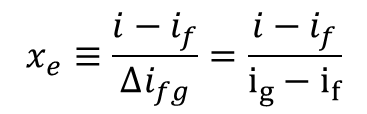

W zadaniu 2.1 liczyliśmy temperaturę, tak samo można policzyć entaplię. Entaplia wzdłuż kanału:

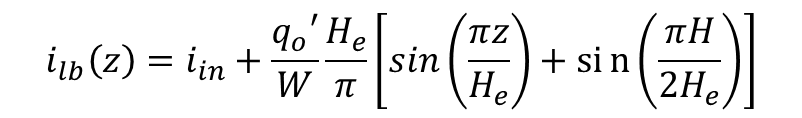

% Entalpia na wejściu do rdzenia
hin = XSteam('h_pT',p,Tin)*1000

hin =    1.3138e+06


% Entalpia wzdłuż kanału
h_lb_max = hin + (q0_prim_max./(W_kanal)).*(He./pi).*(sin(pi .* z ./ He) + sin(pi * H / (2 * He)))

h_lb_max =    1.3138e+06   1.3141e+06   1.3145e+06   1.3151e+06   1.3158e+06   1.3166e+06   1.3176e+06   1.3188e+06   1.3201e+06   1.3215e+06   1.3231e+06   1.3248e+06   1.3267e+06   1.3287e+06   1.3308e+06   1.3331e+06   1.3355e+06   1.3381e+06   1.3408e+06   1.3435e+06   1.3465e+06   1.3495e+06   1.3527e+06   1.3559e+06   1.3593e+06   1.3628e+06   1.3664e+06   1.3701e+06   1.3739e+06   1.3778e+06   1.3817e+06   1.3858e+06   1.3899e+06   1.3942e+06   1.3984e+06   1.4028e+06   1.4072e+06   1.4117e+06   1.4163e+06   1.4209e+06   1.4255e+06   1.4302e+06    1.435e+06   1.4397e+06   1.4445e+06   1.4493e+06   1.4542e+06   1.4591e+06   1.4639e+06   1.4688e+06


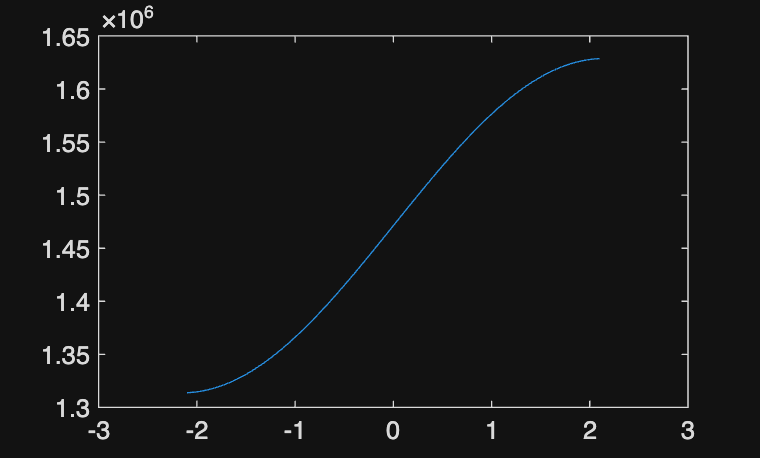

% Wykres entalpii w kanale gorącym
plot(z,h_lb_max)

% Entalpie nasycenia wody i pary dla ciśnienia 155.1 bar - założymy stałe p
h_g = XSteam('hV_p',p)*1000

h_g =    2.5962e+06


h_f = XSteam('hL_p',p)*1000

h_f =    1.6299e+06


% Równowagowy stopień suchości wzdłuż kanału
x_e = (h_lb_max - h_f)./(h_g - h_f)

x_e =      -0.32701     -0.32675     -0.32633     -0.32575     -0.32502     -0.32414      -0.3231     -0.32191     -0.32057     -0.31908     -0.31743     -0.31564     -0.31371     -0.31163     -0.30941     -0.30705     -0.30456     -0.30192     -0.29916     -0.29627     -0.29325      -0.2901     -0.28684     -0.28345     -0.27995     -0.27634     -0.27263      -0.2688     -0.26488     -0.26086     -0.25675     -0.25255     -0.24827      -0.2439     -0.23946     -0.23494     -0.23036     -0.22571       -0.221     -0.21624     -0.21143     -0.20657     -0.20168     -0.19674     -0.19178     -0.18679     -0.18177     -0.17674      -0.1717     -0.16665


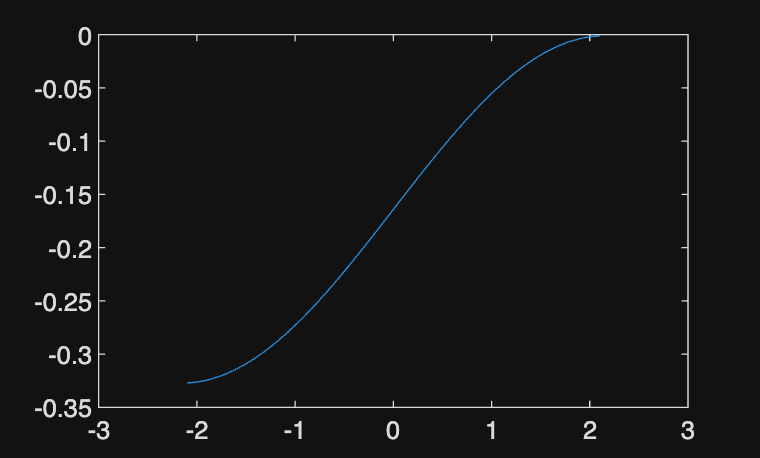

% Wykres
plot(z,x_e)

**Stosowalność korelacji**

•Zakres stosowalności korelacji L&L: 

750<G<5000 [kg/m2/s]

29.4 < p < 196 [bar]

2 < Dh< 45 [mm]

G 

G =        26.095


p

p =    155


Dh*1000

ans =        1689.8


**Właściwe obliczenia q''_cr**

% CHF wzdłuż kanału
q_bis_cr = chf_LevitanLantsman(G,p,x_e,Dh).*1e6  % 1e6 MW/m2 -> W/m2

q_bis_cr =         27960        27981        28015        28061        28120        28192        28276        28373        28483        28605        28740        28889        29050        29224        29411        29611        29825        30051        30291        30544        30810        31090        31384        31690        32011        32345        32692        33053        33428        33817        34219        34635        35064        35507        35964        36434        36917        37414        37923        38446        38981        39530        40090        40663        41247        41844        42451        43070        43698        44338



max(q_bis_max)

ans =    1.2684e+06


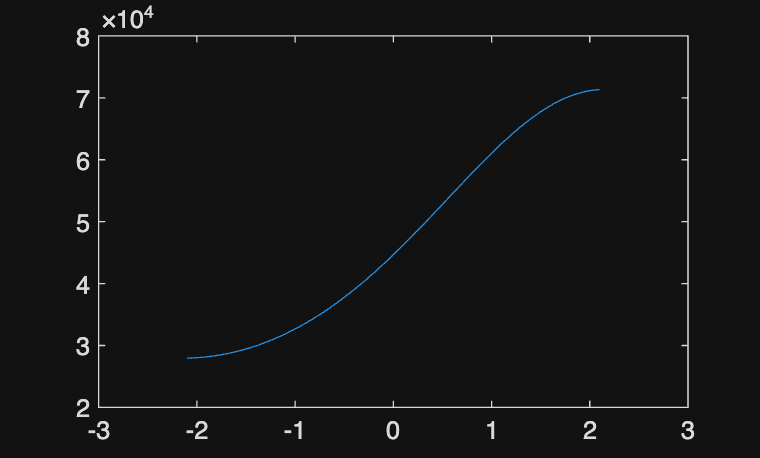

% Wykres
plot(z, q_bis_cr)

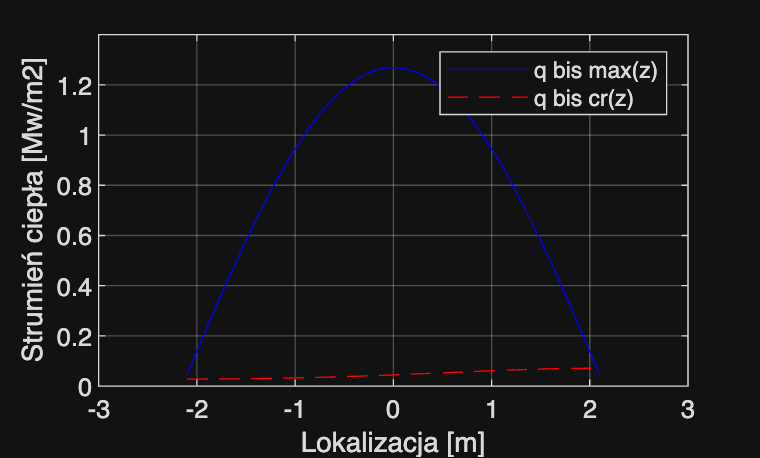

% Wykres porwnujący strumienie q_bis_max oraz q_bis_cr
plot(z, q_bis_max./1e6,'-b',z,q_bis_cr./1e6,'--r'); 
grid on; box on; xlabel('Lokalizacja [m]'); ylabel('Strumień ciepła [Mw/m2]'); legend('q bis max(z)','q bis cr(z)')

**4. Oblicz współczynnik odjeścia od wrzenia pęcherzykowego w najbardziej obciążonym cieplnie miejscu. Wykonaj wykres DNBR wzdłuż kanału.**

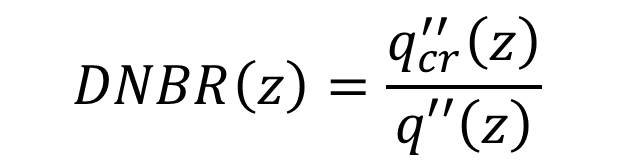

% Obliczenia DNBR
DNBR = q_bis_cr./q_bis_max

DNBR =       0.60347      0.32689      0.22451      0.17127      0.13869      0.11675      0.10101      0.08918     0.079995     0.072672     0.066714     0.061784      0.05765     0.054145     0.051145     0.048557     0.046311     0.044352     0.042635     0.041125     0.039796     0.038622     0.037586     0.036671     0.035864     0.035155     0.034533     0.033992     0.033523     0.033121     0.032782       0.0325     0.032273     0.032096     0.031968     0.031886     0.031848     0.031853     0.031899     0.031985      0.03211     0.032274     0.032476     0.032715     0.032993     0.033308     0.033661     0.034053     0.034484     0.034954


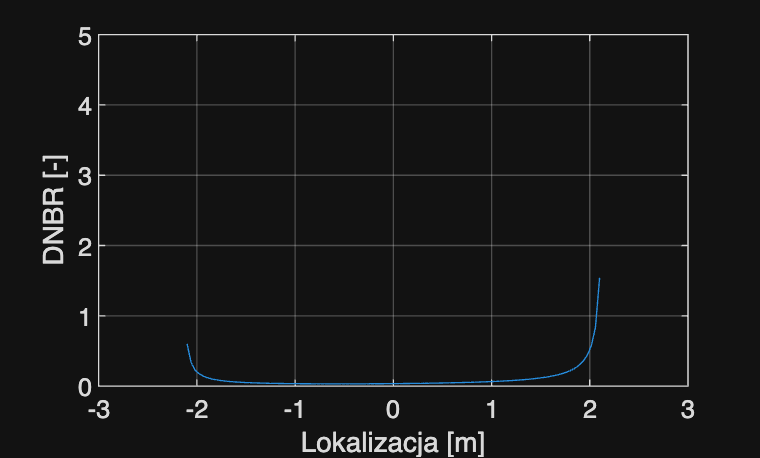


% Wykres
plot(z, DNBR); 
grid on; box on; xlabel('Lokalizacja [m]'); ylabel('DNBR [-]'); ylim([0 5])

**5. Określ wartość MDNBR oraz lokalizację.**

MDNBR = min(DNBR)

MDNBR =      0.031848
